addpath('~/uni/utils')

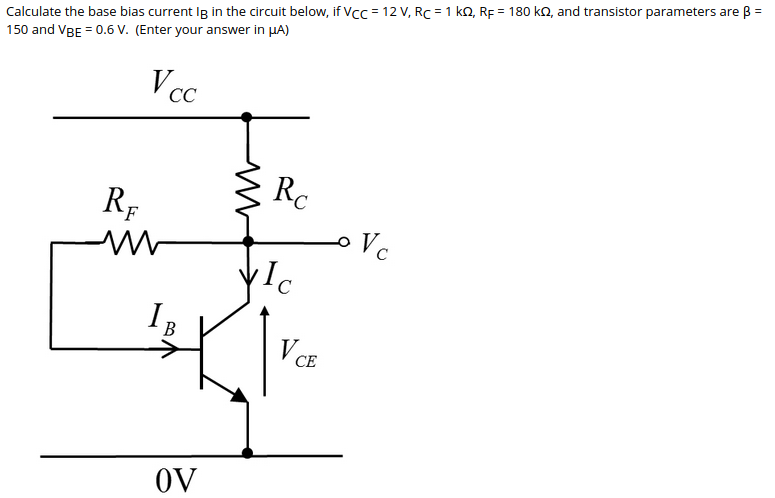

syms V_CC R_F R_C V_C I_C I_B V_CE V_BE beta I_E

constants = [
    V_CC == 12
    R_C == 1e3
    R_F == 180e3
    beta == 150
    V_BE == 0.6
];

kvl_be = V_CC == (I_C + I_B) * R_C + I_B * R_F + V_BE

$$kvl\_be = V_{\mathrm{CC}}=V_{\mathrm{BE}}+R_{C}\,\left(I_{B}+I_{C}\right)+I_{B}\,R_{F}$$

kvl_ce = V_CC == (I_C + I_B) * R_C + V_CE

$$kvl\_ce = V_{\mathrm{CC}}=V_{\mathrm{CE}}+R_{C}\,\left(I_{B}+I_{C}\right)$$

beta_eq = bjt_beta(beta, I_B, I_C, I_E)

$$beta\_eq = \left(\begin{array}{c} I_{C}=I_{B}\,\beta \\ I_{E}=I_{B}\,\left(\beta +1\right) \end{array}\right)$$


solve_for(I_B, [ ...
    constants
    kvl_be
    kvl_ce
    beta_eq
])

$$ans = 3.444e-5$$

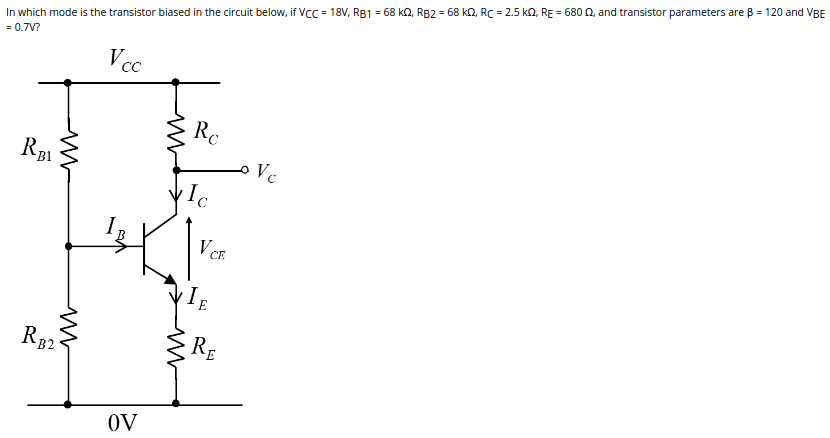

syms R_B1 R_B2 R_E

constants = [
    V_CC == 18
    R_B1 == 68e3
    R_B2 == 68e3
    R_C == 2.5e3
    R_E == 680
    beta == 120
    V_BE == 0.7
];

kvl_b = V_BE + I_E * R_E == vdiv(V_CC, R_B1, R_B2)

$$kvl\_b = V_{\mathrm{BE}}+I_{E}\,R_{E}=\frac{R_{\mathrm{B2}}\,V_{\mathrm{CC}}}{R_{\mathrm{B1}}+R_{\mathrm{B2}}}$$

kvl_ce = V_CC == R_C * I_C + V_CE + I_E * R_E

$$kvl\_ce = V_{\mathrm{CC}}=V_{\mathrm{CE}}+I_{C}\,R_{C}+I_{E}\,R_{E}$$



solve_for(V_CE, [
    constants
    kvl_b
    kvl_ce
    beta_eq
]) % -ve, therefore in saturation

$$ans = -20.56$$

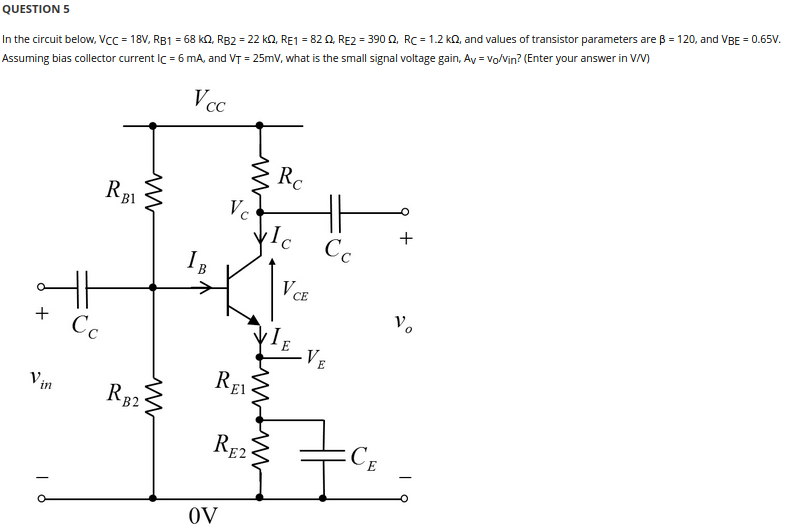

syms R_E1 R_E2 v_in v_out V_BB R_B r_pi A_v
constants = [
    V_CC == 18
    R_B1 == 68e3
    R_B2 == 22e3
    R_E1 == 82
%     R_E2 == 390
    R_C == 1.2e3
    beta == 120
    V_BE == 0.65
    I_C == 6e-3
];


diff_res = diffusion_resistance(beta, 25e-3, I_C, r_pi)

$$diff\_res = I_{C}\,r_{\pi }=\frac{\beta }{40}$$

kvl_v_in = v_in == I_B * r_pi + I_E * R_E1

$$kvl\_v\_in = v_{\mathrm{in}}=I_{B}\,r_{\pi }+I_{E}\,R_{\mathrm{E1}}$$

kvl_v_out = v_out == - I_C * R_C

$$kvl\_v\_out = v_{\mathrm{out}}=-I_{C}\,R_{C}$$

gain = A_v == v_out / v_in

$$gain = A_{v}=\frac{v_{\mathrm{out}}}{v_{\mathrm{in}}}$$


solve_for(A_v, [
    constants
    thev_v
    diff_res
    kvl_v_in
    kvl_v_out
    gain
    beta_eq
])

$$ans = -7.2$$

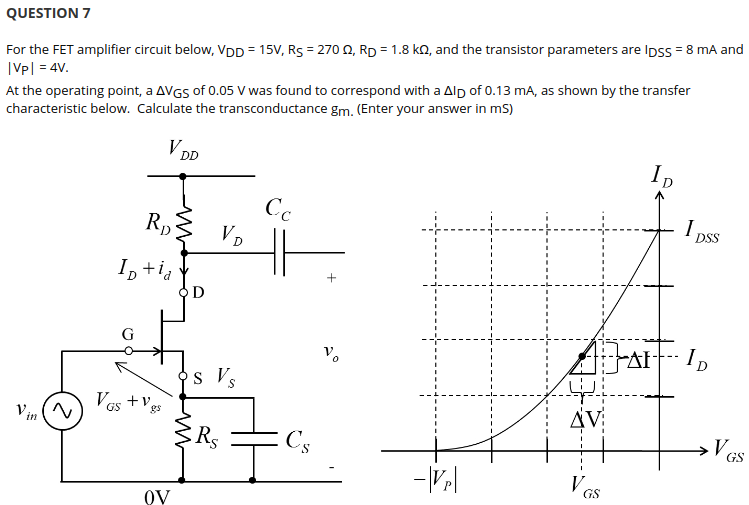

syms V_DD R_S R_D I_DSS V_P Delta_V_GS Delta_I_D g_m
constants = [
    Delta_V_GS == 0.05
    Delta_I_D == 0.13e-3
]

$$constants = \left(\begin{array}{c} \Delta_{V,\mathrm{GS}}=\frac{1}{20}\\ \Delta_{I,D}=\frac{13}{100000} \end{array}\right)$$


trans_conductance = g_m == Delta_I_D / Delta_V_GS

$$trans\_conductance = g_{m}=\frac{\Delta_{I,D}}{\Delta_{V,\mathrm{GS}}}$$


solve_for(g_m, [constants; trans_conductance])

$$ans = 0.0026$$

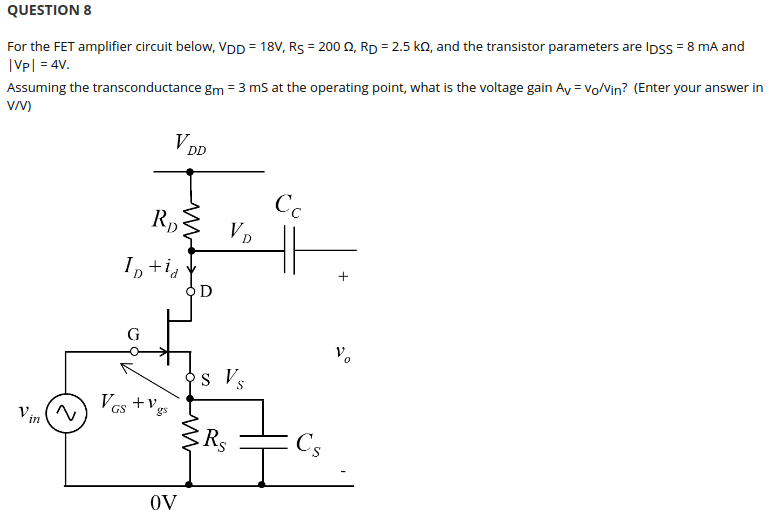

syms A_v v_o v_in

constants = [
    V_DD == 18
    R_S == 200
    R_D == 2.5e3
    V_P == 4
    I_DSS == 8e-3
    g_m == 3e-3
]

$$constants = \left(\begin{array}{c} V_{\mathrm{DD}}=18\\ R_{S}=200\\ R_{D}=2500\\ V_{P}=4\\ I_{\mathrm{DSS}}=\frac{1}{125}\\ g_{m}=\frac{3}{1000} \end{array}\right)$$


small_signal_vo = v_o == -g_m * R_D * v_in

$$small\_signal\_vo = v_{o}=-R_{D}\,g_{m}\,v_{\mathrm{in}}$$

gain_def = A_v == v_o / v_in

$$gain\_def = A_{v}=\frac{v_{o}}{v_{\mathrm{in}}}$$


solve_for(A_v, [constants; small_signal_vo; gain_def])

$$ans = -7.5$$

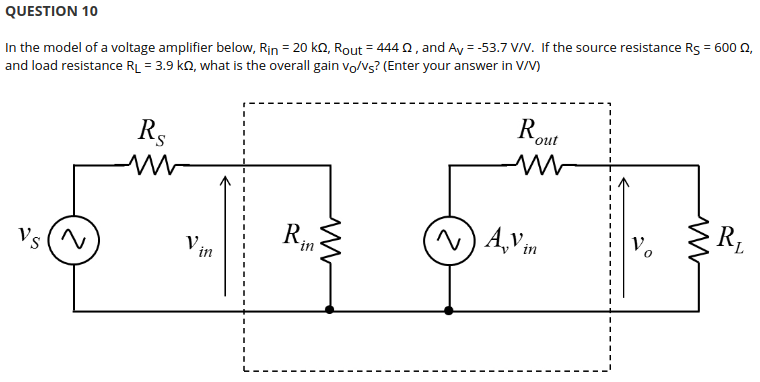

syms R_in R_out R_L v_s

constants = [
    A_v == -53.7
    R_in == 20e3
    R_out == 444
    R_S == 600
    R_L == 3.9e3
]

$$constants = \left(\begin{array}{c} A_{v}=-\frac{537}{10}\\ R_{\mathrm{in}}=20000\\ R_{\mathrm{out}}=444\\ R_{S}=600\\ R_{L}=3900 \end{array}\right)$$


input = v_in == vdiv(v_s, R_S, R_in)

$$input = v_{\mathrm{in}}=\frac{R_{\mathrm{in}}\,v_{s}}{R_{S}+R_{\mathrm{in}}}$$

output = v_o == vdiv(A_v * v_in, R_out, R_L)

$$output = v_{o}=\frac{A_{v}\,R_{L}\,v_{\mathrm{in}}}{R_{L}+R_{\mathrm{out}}}$$

gain = v_o / v_s

$$gain = \frac{v_{o}}{v_{s}}$$


% Why doesn't this work???
% solve_for(gain, [constants; input; output])
solve_for(A_v * R_L * R_in / ((R_L + R_out) * (R_S + R_in)), constants)

$$ans = -46.81$$